# Digital Control Homework: Differential Drive Robot 

Giorgia Disarò, email*: giorgia.disaro@phd.unipd.it *

In the following exercises, we are going to apply the digital control methos to synthetize 3 compensators for a **differential drive robot (DDR), **whose wheels are driven by two **DC brushed motors**. 

A DDR of this type is shown in *Figure 1* below along with its representation in the Cartesian plane. Robots with such a drive are very sensitive to slight changes in velocity in each of the wheels. Small errors in the relative velocities between the wheels can affect the robot trajectory. Moreover, they are also very sensitive to small variations in the ground plane and so typically they have one or more castor wheels to prevent the vehicle from tilting. 

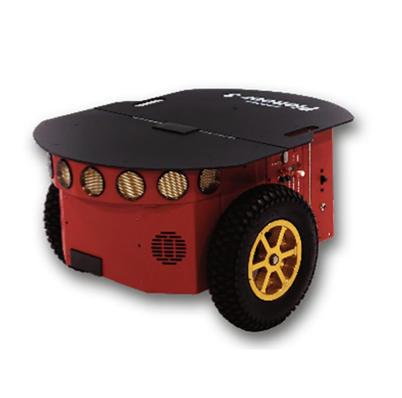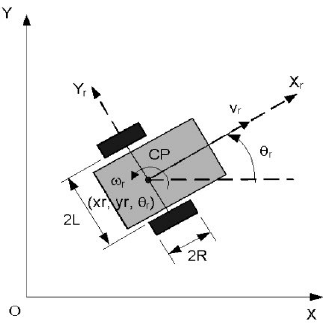

*Figure 1: DDR (on the left); Cartesian representation of the DDR system (on the right)*

The scheme of a DC brushed motor and its electromechanical circuit are illustred in *Figure 2*.

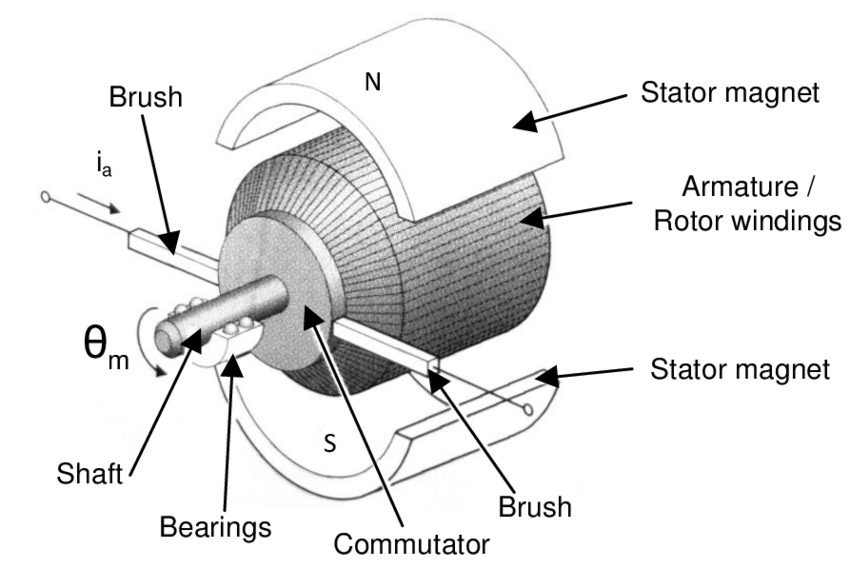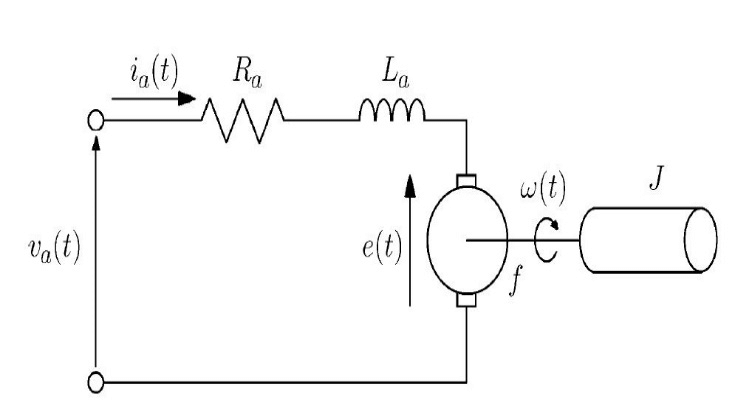

*Figure 2: Schematic representation of a DC brushed motor (on the left); Circuit of the DC brushed motor (on the right)*

The transfer function of the motor can be easily derived and is reported here: 

$\frac{\omega}{V}=\frac{K}{(JL)s^2+(JR+bL)s+bR+K^2}$,

where we have omitted all the subscripts to ease the notation. Moreover, we have also adopted the simplifying hypothesis that the voltage constant and the torque constant coincide and are both denoted by $K$. 

We suppose that the motors driving the two wheels are described by slightly different parameters that are listed below along with the other paramters describing the system. 

Moreover, we also provide the transfer functions of the motors driving the two wheels. 

%% LEFT WHEEL
% Parameters of the model of the left wheel 

R_l = 13;         % resistance [Ohm]
L_l = 52e-3;      % inductance [H]
K_l = 0.2;        % motor constant [Nm/A]
J_l = 2.4e-4;     % inertia [kgm^2]
b_l = 1e-8;       % viscous friction [Nms]

% Transfer function of the model 
s = tf('s');
P_l = K_l / (J_l * L_l * s^2 + (R_l * J_l + b_l * L_l) * s + (K_l^2 + R_l * b_l));

%% RIGHT WHEEL
% Parameters of the model of the right wheel

R_r = 8;          % resistance [Ohm]
L_r = 45e-3;      % inductance [H]
K_r = 0.25;       % motor constant [Nm/A]
J_r = 2.4e-4;     % inertia [kgm^2]
b_r = 1e-8;       % viscous friction [Nms]

% Transfer function of the model 
P_r = K_r / (J_r * L_r * s^2 + (R_r * J_r + b_r * L_r) * s + (K_r^2 + R_r * b_r));

%% Other parameters of the model 

r = 0.03;       % radius of the wheels [m]
d = 0.16;       % distance between the two wheels [m]
w_ref = 5;      % reference for the angular velocity of the wheels [rad/s]
Vbat = 15;      % saturation value for the voltage [V]

In the following, the angles denoted by $\theta_r$ in Figure 1 will be simply denoted by $\theta$ for simplicity.

Our **goal** is to make the DDR follow a straight line, which amounts to saying that the yaw angle $\theta$ must be equal to zero. Thus, once we have reached the steady state, the two wheels have to rotate at the same angular velocity, that we call $\omega_{ref}$. However, if the DDR initially has a different space configuration, meaning that $\theta(0)$ is not zero, the two wheels need to rotate at different angular velocity in order to first orient the robot in the correct way. Try with different initial conditions (you have to set them in the *Integrator* block inside the *Differential Drive Subsystem* in the Simulink scheme) .

Since we are using a digital control strategy, we have to deal with all the effects introduced by the discretization of the signals into play, related to **sampling** and **quantization**. Therefore, the chioces of the sampling time and of the quantization steps used in our control scheme strongly affect the perfermance of our system, as we will see during the following experiments.

Here are the values of the sampling time, which is the same for the whole scheme, and of the various quantization steps.

%% Discretization parameters

Ts = 1e-3;         % sampling time [s]
delta_q1 = 1e-3;   % input quantization step [V]
delta_q2 = 5e-5;   % output quantization step [rad/s]
delta_q3 = 1e-5;   % line quantization step [rad] (Try for instance with 1e-4, pi/72)

To achieve our control goal, we make use of **3 controllers**:

- a controller for the angular velocity of the DC brushed motor of the left wheel, say $C_1(z)$, used to follow our reference signal $\omega_{ref}$;

- a controller for the angular velocity of the DC brushed motor of the right wheel, say $C_2(z)$, used to follow the same reference signal $\omega_{ref}$;

- a controller for the whole system constituted by the the two DC brushed motors and the DDR itself, say $C_3(z)$, responsible of the main target of the implemented control architecture, namely bringing $\theta$ to zero. 

 The resulting scheme of the configuration described above is given in the following **Simulink** file. 

open("ModelScheme.slx")

In the Simulink scheme we have also added some small constant **disturbances **in the angular velocity of the two wheels, in order to get an idea of how the system responds to the presence of noise since, as we have already highlighted, it is very sensitive to this kind of changes. Test the performance of the designed control scheme with or without the various noises by enabling/disenabling the corresponding branches in the scheme by means of the inserted manual switches. Try to increase the noise amplitude and **interpret the results** you obtain. *Comment below...*

## Assignment 1

**(a)**  As first task, we design a controller for the angular velocity of the DC brushed motor of the left wheel of the DDR, in order to make the motor able to rotate at the desired angular velocity. Design this controller by means of the **Emulation Method **and more specifically, of the **Tustin transformation**. Try to obtain the best performance you can and remember that we need to follow a step reference. (Hint: Try first with simple controllers, like P, PI and PID controllers.) 

% C1 = ...complete with the tf of the controller...
% we want tr = 0.01s and mp = 0, so wc = 2 / tr = 200 rad/s
% and mph = 1.04 - 0.8 * mp = 1.04 rad
% the additional phase margin is due only to the holder
% we have positive phase margin in [0, pi] and we need to
% track a step, so we need a PID

tr = 0.01; % [s]
mp = 0;
wc = 2 / tr;
mp = 1.04 - 0.8 * mp;
mph = wc * Ts / 2;
mpt = mp + mph;

K_I_l = 100;
1 / cos(mpt)

ans = 2.3947


M_l = wc / (K_I_l * abs(freqresp(P_l, wc)));
M_l

M_l = 7.7475

m0_l = angle(freqresp(P_l, wc));

T_I_l = 0;
T_D_l = 0;

C1 = K_I_l / s * (1 + T_I_l * s + T_D_l + T_I_l * s^2);
C1 = c2d(C1, Ts, "tustin");

N_C1 = C1.Numerator{1};
D_C1 = C1.Denominator{1};

**(b)**  The second task is very similar to the first one since we have to design a controller that does the same thing of the previous one, but we need to take into account that this compensator acts on the right wheel whose motor has slightly different parameters in the transfer function. Use again the **Emulation Method** with **Tustin**. Take into account that the resulting closed-loop transfer functions of the two wheels have to be almost the same, meaning that the two controllers must lead to very similar performance. 

% C2 = ...complete with the tf of the controller...
C2 = s;
C2 = c2d(C2, Ts, "tustin");

N_C2 = C2.Numerator{1};
D_C2 = C2.Denominator{1};

## Assignment 2 

Now it only remains to design the third controller that receives as input the error on the yaw angle $\theta$ and provides the value of the angular velocity of the body needed to compensate the deviation, but already converted to variation in the angular velocity of the wheels, say $\Delta \omega$. This quantity $\Delta\omega$ needs to be added to the reference in the right wheel and subtracted in the left wheel in order to produce the correct rotation. 

To achieve the final goal, **synthetize the controller directly** in the digital domain. Before designing the controller, find the continuous-time transfer function of the to-be-controlled plant, say $P_{tot}(s)$. (Hint: Follow the Simulink scheme to obtain this transfer function.) Once you have found the transfer function of the plant for which we want to design the controller, discretize it using the exact discretization method and obtain $\tilde{P}(z)$. Design $C_3(z)$, using the **discrete root locus** obtained with the command `rlocus`. Choose the option *Grid * by clicking the right button to disply the reference grid. Based on the root locus plot, try to design a controller that guarantees a good trade-off between simplicity and performance. If you already have experienced the *Control System Designer* of Matlab or if you want to try, you can also use this tool with the the command `sisotool` to design the controller by exploiting the root locus (use only the right half of the interface). 

% C3 = ...complete with the tf of the controller...
N_C3 = C3.Numerator{1};
D_C3 = C3.Denominator{1};

## Assignment 3

We assume that the signal corresponding to the angle $\theta$ is being measured with a **line sensor**, *as the one in Figure 3*. A line sensor is a device made of various sensors each of which detects the presence of a black line by emitting infrared (IR) light and then measuring the light level that returns to it. They do this using two components: an emitter and a light sensor (receiver). The device will emit IR light, and the sensor will capture the light level that is reflected from the surface underneath it. The digital output results from a comparison of the light levels against a threshold level that is adjusted by tuning the potentiometer. If the sensor does not receive enough light to surpass the threshold value, the digital output will be high (1). If enough light is received and the threshold value is surpassed, the output will be set to low (0). To model this device, we introduce in the control scheme a quantizer, whose quantization step models the distance between two adjacent sensors and thus the precision in measuring the angle $\theta$. 

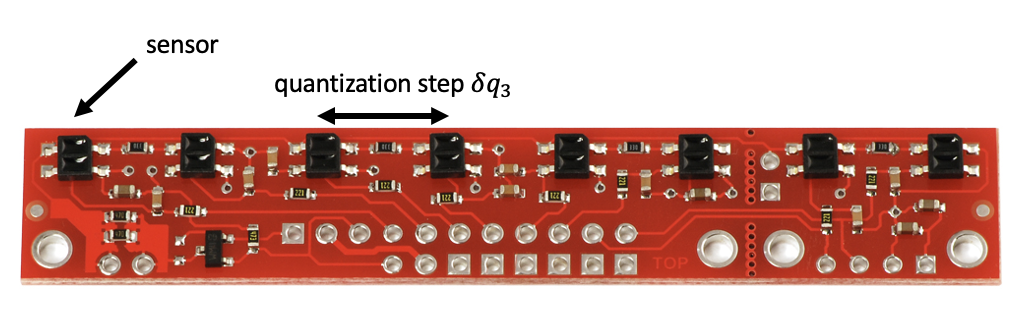

*Figure 3: Line sensor*

At the beginning we simulate the system setting the quantization step to a small value. However, usually line sensors are not so dense, so it would be more realistic if we increased the quantization step. **Try different values of the quantization step **(such as the ones suggested above)** and examine how this choice affects the system. **Try to explian why.  

(Hint: Take into account that in the considered model, for the sake of simplicity, the target line is attached to the robot center and always parallel to the $x$-axis...)

*Comment here...*

## Assignment 4

To conclude, we add an **Anti-Aliasing Filter** in order to avoid that high-frequency disturbances have effect also at low frequencies, deteriorating the performance of the adopetd digital control strategy. Design a $\mathbf{2^{nd}}$** order anti-aliasing filter** and test the perfomance of the digital controlled system in the presence of some additive disturbance $d(t)$ that enters in the output branch of the control loop. In particular, we suppose that the disturbance is a sum of sinusoids with different amplitudes and frequencies. 

In the Simulink scheme use the two manual switches to incorporate also the anti-aliasing filter in the control loop and to test the performance with or without the filter. 

% A = ...complete with the tf of the filter...

## Assignment 5 (Advanced) 

In order to better understand what happens inside a controller, and more specifically a digital controller, try to substitute one or more of the previous compensators with a **MATLAB Function block** in Simulink where you implement in the time domain what the controller is practically doing on the signals. Remember to set the samling time to $T_s$ in the *Block Parameters*. (Hint: See what `persistent` variables are...)